# **Nonlinear mapping**

Oftentimes we want to capture the impact of a continuous variable $x$ and cannot assume *a priori *that this impact is linear in $x$. So we would like to capture contributions to the predictor in the form of $f(x)$ where $f$ is an unknown function we want to estimate from the data. This problem is usually known as Generalized Additive Models. In the GUM toolbox, you can include them simply by including regressors of the form `f(x) `to your formula. For example, to include a model where $x$ has a nonlinear impact while $z$ has a linear impact on the predictor, write the formula as `'y ~ f(x) + z'`. Nonlinear mapping can be treated in two different ways: using *basis functions* or *Gaussian Processes*. We start with basis functions because they are more intuitive, but Gaussian Processes are more powerful and are the default option.

We will use the same dataset as in [getting_started.mlx](matlab:open('getting_started.mlx')). A monkey decides on each trial whether a motion in a complex visual stimulus is more towards the left or right. We will build throughout the tutorial regression model where we want to predict the response of animal based on different regressors.

T = load_online_dataset();

loading csv file from url...done


head(T)

    resp    target    session     Stimulus     Stimulus1    Stimulus2    Stimulus3    Stimulus4    Stimulus5    Stimulus6    Stimulus7    accuracy     signed_resp
    ____    ______    _______    __________    _________    _________    _________    _________    _________    _________    _________    _________    ___________

     0        0          1       1×7 double       -10           -9          -10           -7          -13          -12          -11       "correct"        -1     
     0        0          1       1×7 double        -8          -10  

### **Basis functions**

When using basis functions, we basically constrain the function $f$ to take the form $f(x) = \sum_k \beta_k b_k(x)$ where $b_k$ are a set of fixed basis functions. For example if we use polynomials, then $b_0(x) = 1$, $b_1(x)=x$, $b_2(x)=x^2$, and so on. In this case, we substitute the complicated problem of estimating function $f$ by the much simpler problem of estimating a set of weights $\beta_k$ , which basically gets you back to fitting a standard GLM. The downside is of course that you are limiting the flexibility of the function to the set of basis functions (if you're using just polynomials of order 1... wait, this is exactly just a linear function).

You can declare a nonlinear mapping with basis function using the syntax `f(x; basis=str)` or `str(x) `where `str` is the name of a basis function. For example `str=poly3` will give you polynomials of order 2 (so $b_0(x) = 1$, $b_1(x)=x$, $b_2(x)=x^2$, $b_3(x)=x^3$), e.g. will estimate a cubic function.

In our example let's try to capture the change in animal lateral bias across session using a cubic function of session. (We use a subsample of trials to see how the model operates in a regime with low statistical power, which is where it is most helpful).

subset = 1:20:height(T); % just one every 20 trials
M = gum(T(subset,:), 'resp ~ poly3(session)').infer;
figure;

Evaluating prior covariance matrix...done
****
converged after 4 iterations, log-joint:-2491.846897
Computing posterior covariance...done


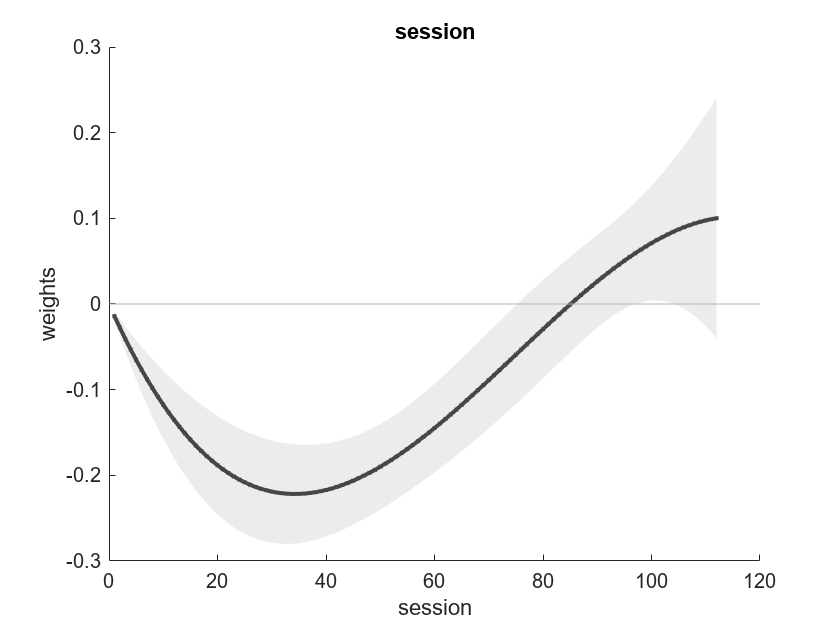

M.plot_weights;

You can visualize the set of basis functions using `plot_basis_functions`:

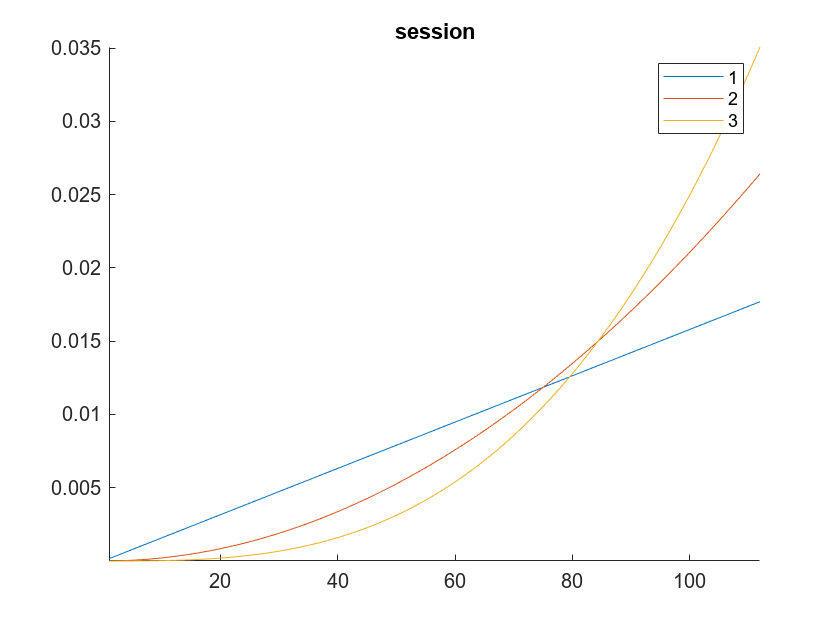

figure;
M.plot_basis_functions([],'normalize'); % we use the normalize option because otherwise x^3 takes on much larger valuesYou can also 

You can also inferred the estimated weights for each basis functions (i.e. the coefficients $\beta_k$) by projecting the weights onto the space of basis functions prior to plotting. Weight at position 1, 2 and 3 corresponds to the weight for the linear, quadratic and cubic term, respectively.

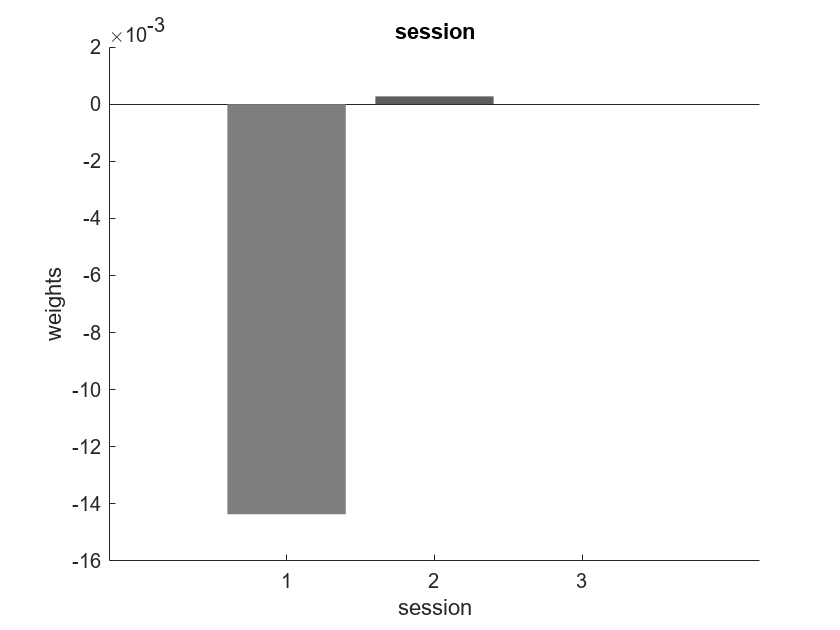

M.regressor = M.regressor.project_to_basis;
figure;
M.plot_weights;

Here's the complete list of basis functions you can use

- **polynomials**: define a polynomial function of $x$ using `polyN(x)` or `f(x;basis=polyN)` where `N` is an integer defining the polynomial degree (e.g. `poly5(x)` is a 5th order polynomial). Note that the 0th degree polynomial, equivalent to an intercept ($b_0(x)=1$), is not included - except when the regressor is multiplied with another one, e.g. `poly3(x)*cat(y)`. If the input space is multidimensional, then $f$ is a [multilinear polynomial](https://en.wikipedia.org/wiki/Multilinear_polynomial). For example, `poly3(x,y) `defines the regressor $x, y, x^2, xy, y^2, x^3, x^2y, xy^2$ and $y^3$.

- **exponentials**: you can use exponential basis functions $b_k(x) = \frac 1 \tau_k \exp(-x / \tau_k)/$ using `expN(x)` or `f(x;basis=expN)` where `N` is an integer defining the number of exponential functions. The scale $\tau_k$ are hyperparameters which can be fitted to the data using `fit()` - see more in the tutorial about hyperparameter fitting. You can set/initialize their value using the syntax `expN(x;tau=tau1,...). `For example `exp2(x; tau=3,10)` uses 2 basis functions, one with scale 3 and the other with scale 10.

- (non-normalized) [**gamma distribution**](https://en.wikipedia.org/wiki/Gamma_distribution) (not to be confounded with gamma functions), $b_k(x) = x^{K_k-1} \exp(-x/\theta_k)$ if $x>0$ and $b_k(x)=0$ otherwise. $K_k$ and $\theta_k$ are the shape and scale of the basis function. hyperparameters used for example in [Knapen et al. *Plos One* 2016](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0155574)

- **raised-cosine**,  [Pillow et al. *Nature* 2008](https://www.nature.com/articles/nature07140)

Weights for the basis functions $\beta_k$ have **gaussian prior **with constant variance. As for linear regressors, you can set the value of the variance hyperparameter with the `variance `option, i.e.` exp2(x;variance=10) `uses a gaussian prior with variance 10`. `You can also remove the prior by declaring `prior=none, `e.g. `exp3(x; prior=none)`; or change the prior to automatic relevance determination (ARD, i.e. one variance hyperparameter for each basis function) by declaring` prior=ARD.`

#### Gaussian Processes

The other framework for capturing nonlinear mapping is Gaussian Processes (GPs). This is what is applied by default, if we simply define the function in our formula by `f(x)`. In GPs, we do not define a set of basis functions, or rather we use an infinite set of basis functions. So the type of function that can be captured is not bound by this set of basis functions but can be adjusted to the statistical power of the regression problem. The magic of GPs lies is that it imposes a prior over function evaluations $f(x_i)$ that constrains the inferred function to be smooth. We generally use the Squared Exponential kernel which is a very common way to parametrise the smoothness of functions. It depends on two hyperparameters: a variance parameter (which can be set by using option `variance`) with scales the general variance of the prior; and a scale parameter (which can be set using option `tau`), which determines the scale at which the function varies (the larger `tau` is, the smoother will be the inferred function). Let's see in practice how changing the hyperparameter affects the inferred function on the same example as previously:

subset = 1:20:height(T); % just one every 20 trials
M(1) = gum(T(subset,:), 'resp ~ f(session) + 0',struct('label','de fault'));
M(2) = gum(T(subset,:), 'resp ~ f(session;tau=30) + 0',struct('label','tau=30'));
M(3) = gum(T(subset,:), 'resp ~ f(session;variance=.001) + 0',struct('label','variance=0.001'));

Inferring weights for model 1/3 (de fault)
Evaluating prior covariance matrix...done
****
converged after 4 iterations, log-joint:-2487.065277
Computing posterior covariance...done

Inferring weights for model 2/3 (tau=30)
Evaluating prior covariance matrix...done
****
converged after 4 iterations, log-joint:-2490.711637
Computing posterior covariance...done

Inferring weights for model 3/3 (variance=0.001)
Evaluating prior covariance matrix...done
****
converged after 4 iterations, log-joint:-2490.134724
Computing posterior covariance...done



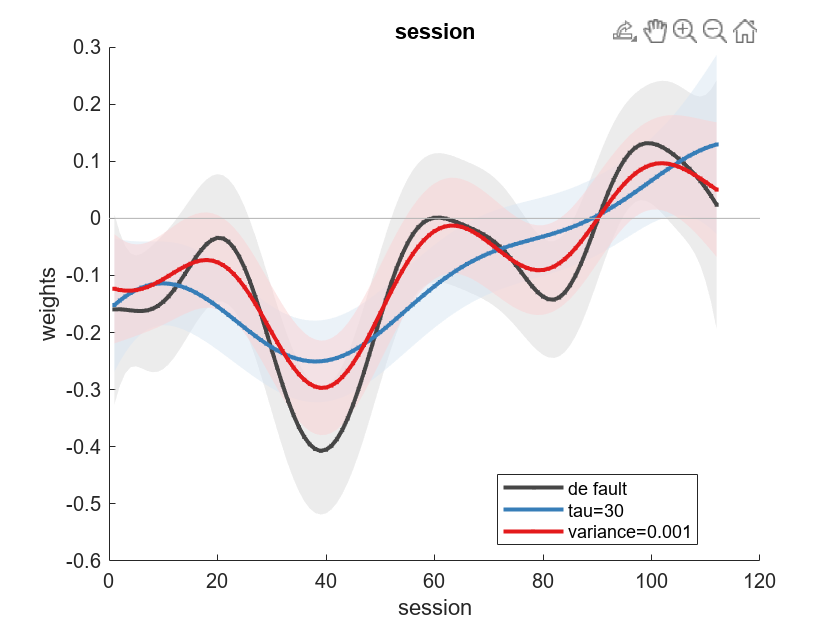

M = M.infer(); % infer all models at once
Mc = M.concatenate_over_models; % concatenate results in a single model object for plotting

figure; Mc.plot_weights;

Evaluating prior covariance matrix...done
****
converged after 4 iterations, log-joint:-2483.818363
Computing posterior covariance...done


#### Other options

- You can also create **functions of two variables** `x` and `y `using the syntax `f(x,y). ` You can even define functions of even more variables: `f(x,y,z,...),`but inference is usually difficult in higher dimensions (larger than 2), so this is probably not a good option unless you know what you are doing. This only works for the GP framework or for polynomial basis functions.

- You can estimate different functions of `x `depending on a categorical variable `x` by using the syntax `f(x)|z` or `f(x|z)`. 

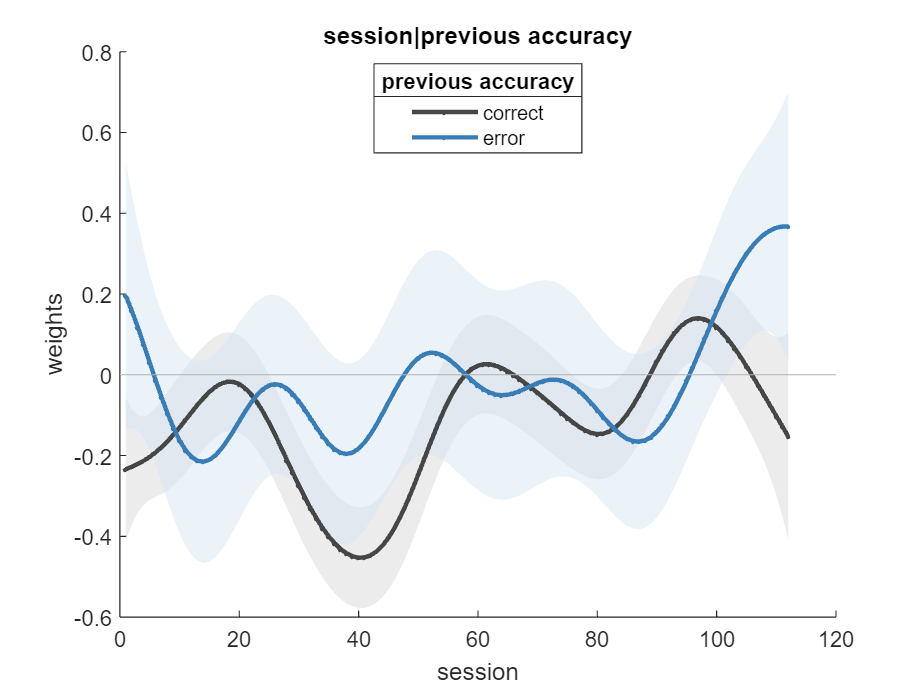

M = gum(T(subset,:), 'resp ~ f(session)|lag(accuracy) + 0').infer;

Evaluating prior covariance matrix...done
Fitting weights, starting point 1/10
***
converged after 3 iterations, log-joint:-49921.266047
Fitting weights, starting point 2/10
****x>>>>o>>>>x>>>>O>>>>x>>>>o>>>>x>>>>O>>>>x>>>>o
converged after 50 iterations, log-joint:-29418.709298
Fitting weights, starting point 3/10
***>x>>>>o>>>>x>
converged after 16 iterations, log-joint:-29418.709298
Fitting weights, starting point 4/10
****x>>>>o>>>>x>>>>O>>>>x>>>>o>>
converged after 32 iterations, log-joint:-29418.709298
Fitting weights, starting point 5/10
****x*>>>o>>>>x>>>>O>>>>x>>
converged after 27 iterations, log-joint:-29418.709298
Fitting weights, starting point 6/10
****x>>>>o>>>>x>>>>O>>>>x>>
converged after 27 iterations, log-joint:-29418.709298
Fitting weights, starting point 7/10
****x>>>>o>>>>x>>>>O>>>>x>>>>o>>>>x>>>>
converged after 39 iterations, log-joint:-29418.709298
Fitting weights, starting point 8/10
****x>>>>o>>>>x>>>>O>>>>x>>>>o>>>>x>>>>O>>>>x
converged after 45 iterations, 

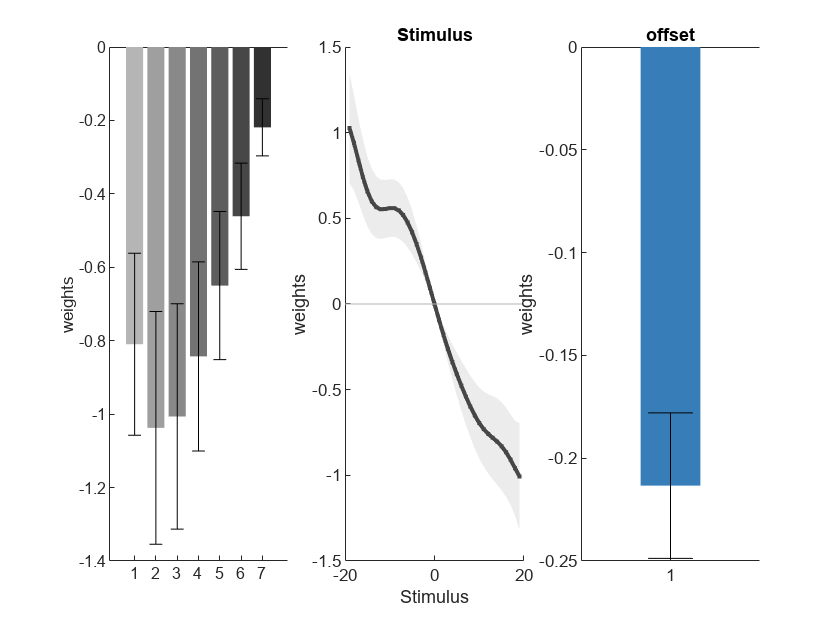

figure; M.plot_weights;

- It is possible to bin values of x prior to using the nonlinearly with the syntax `f(x;binning=N) ` where `N `is an integer defining the number of quantiles to use for binning. This may speed up model estimation in some cases.

- You can select a linear constraint to be applied to the set of weights with the option `f(x;constraint=str)` where `str` is one of the following options: ` free `(no constraint), `fixed `(all weights are fixed), `zero0 `(the value of the function at 0 is 0), `mean1` (the mean value of the function is 1), `sum0` (the sum of values of the function overall all levels is 0), `sum1 `(the sum of the values of the function over all levels is 1), `first0 `(the value of $f(x)$ for the lowest $x$ in the sample is null) and `first1 `(the value of $f(x)$ for the lowest $x$ in the sample is 1). Note that if the function uses basis functions, the constraint is defined in the original space and not on the weights of the basis functions. See the section on [constraint on weights](matlab:open('./building_a_model.mlx')) for further details. 

#### Multidimensional input variable

If `x` is a vector and not a scalar, there are multiple ways to apply the nonlinearity, which are controlled by the option parameter `sum:`

- By default `f(x)` will add the weighted sum $\sum_i w_i f(x_i)$ to the predictor, where $w_i$ is a specific weight and $f$ is a nonlinearity that is common to all dimensions $x_i$. You can view it as an extension of the standard linear terms $\sum_i w_i x_i$ (as in `y ~ x`), where where the nonlinearity $f$ has been introduced.  Note that in this case because of the multiplication between $w_i$ and $f(x_i)$ in the formula the model is no-longer a GAM but a GUM, which means that model estimation takes in general longer and may suffer from local minima. This call is equivalent to `f(x;sum=weighted)`.

- `f(x; sum=equal)` assumes equal weighting of all nonlinearities (i.e. $w_i=1$) by adding $\sum_i f(x_i)$ to the predictor. Again, the nonlinearity $f$ is common to all input dimensions $x_i$.

- `f(x; sum=split) `models a different nonlinearity $f_i$ for each dimension of the input space, i.e. adds $\sum_i  f_i(x_i)$. One nonlinearity will be estimated for each dimension $x_i$ (although the hyperparameters are shared between all functions). This provides extra-flexibility compared with the default option which assumes that nonlinear functions differ only by a scaling factor (i.e. $f_i(x_i) = w_i f(x_i)$ ).

- `f(x; sum=joint)` defines a nonlinearity of the multidimensional input space, i.e. $f(x_1,_2...x_N)$, i.e. it does not imposes that the function of the multidimensional spaces decomposes into a sum of function for each dimension $f_1(x_1)+...f_N(x_N)$. This is the most flexible functional form but will usually require a large dataset for accurate model estimation.

This option in the formula can be combined with all other options in the formula, i.e. you can define `poly5(x;sum=split)` or `f(x;basis=poly5;sum=split)` to capture a 5th order polynomial separately for each dimension of $x$.

We illustrate this feature by introducing `f(Stimulus)` in the formula. We can now capture some nonlinear mapping between the stimulus evidence (a signed integer) and its impact onto the decision. We also recover the different weight of the stimulus onto the decision depending on their position in the 7-element sequence.

M= gum(T, 'resp ~ f(Stimulus; constraint=zero0)').infer;
figure;
M.plot_weights;